clear all
close all


%here i define parameters in the tree level calculus
x1=1500;
x2=2560;
x3=4000;
a1=10;
a2=10;
a3=10;
b1=1.2e+1;
b2=1.2e+1;
b3=1.2e+1;
%Majorana masses
m1=8.5e+10;
m2=9.5e+11;
m3=1.1e+11;
m5=1.2e+11;
m6=1.15e+11;


%leptons mass in ev
me=[500000;105650000; 1776820000];
%another parameters of the u(1) model
u=1e+6;
v=1.74e+11;
sk=u/sqrt(u^2+v^2);
%Lepton Yukawa matrix
Y=[0.0245 0.0231 0.0438 ; 0.05134 0.0498 0.0591 ; 0.08 0.0696 0.0257];
%Renormalization scale (betw 6.420 and 6.440)
Q=6.435e+22;%6.435
%Dirac and majorana matrices
md=[x1 x2 x3 ; a1*x1 a2*x2 a3*x3 ; 0 0 0];
mr=[m1 sqrt(m1*m2) sqrt(m1*m3) ; sqrt(m1*m2) m2 sqrt(m2*m3) ; sqrt(m1*m3) sqrt(m2*m3) m3];
mvnose=-md*inv(mr)*md';

%check the seesaw before corrections
[nose,noseig]=eig(mvnose)

nose =    -0.9950   -0.0995         0
    0.0995   -0.9950         0
         0         0    1.0000


noseig = 	1.0e+13 *

    0.0000         0         0
         0    4.9498         0
         0         0         0


%Neutrino yukawa couplings
Yv=md/u;
%masses of u(1) model
mh=2.5e+11;
mx=2e+11;



%Correction for 1 loop of dirac matrix
md22c=0;
md23c=0;
md32c=0;
md33c=0;
mdv=0;
coef=(1/(32*pi^2*mh^2));
mdextra=mh^2*log(mh^2/Q);
for i=1:3
    md22c=md22c+(Y(2,i)*Yv(i,2)*me(i));
    md23c=md23c+(Y(2,i)*Yv(i,3)*me(i));
    md32c=md32c+(Y(3,i)*Yv(i,2)*me(i));
    md33c=md33c+(Y(3,i)*Yv(i,3)*me(i));
    mdv=mdv+(me(i)^2*log(me(i)^2/Q));
end
corr122=md22c*coef*2*sk*(mdv-mdextra)

corr122 = 1.4059e-04

corr123=md23c*coef*2*sk*(mdv-mdextra)

corr123 = 2.1967e-04

corr132=md32c*coef*2*sk*(mdv-mdextra);
corr133=md33c*coef*2*sk*(mdv-mdextra);

%Correction for 2 loops dirac matrix

x=mh^2;
y=(3.2e+11)^2; %typical value of mr
I=(1/x^2)*(2*(x-y)*(dilog(1-(y/x))-log((x-y)/Q)*log(x/y))+(x-(3*y/4))*(log(x/Q))^2+(2*x+y)*log(x/Q)*log(y/Q)+y*(pi^2/6)+(y/2)*(log(y/Q))^2);

loop22=0;
loop23=0;
loop32=0;
loop33=0;

for f=1:3
    for k=1:3
        for l=1:3
            for m=1:3
                for n=1:3
                    loop22=loop22+(Y(2,f)*Yv(f,k)*Yv(m,l)*Yv(m,n)*sk*me(f)*mr(k,l)*mr(n,2));
                    loop23=loop23+(Y(2,f)*Yv(f,k)*Yv(m,l)*Yv(m,n)*sk*me(f)*mr(k,l)*mr(n,3));
                    loop32=loop32+(Y(3,f)*Yv(f,k)*Yv(m,l)*Yv(m,n)*sk*me(f)*mr(k,l)*mr(n,2));
                    loop33=loop33+(Y(3,f)*Yv(f,k)*Yv(m,l)*Yv(m,n)*sk*me(f)*mr(k,l)*mr(n,3));
                end
            end
        end
    end
end

corr222=(md(2,2)/(1e+11))*loop22*I

corr222 = 2.6426e-10

corr223=(md(2,3)/(1e+11))*loop23*I

corr223 = 1.4050e-10

corr232=(md(3,2)/(1e+11))*loop32*I;
corr233=(md(3,3)/(1e+11))*loop33*I;

%the the final correction
mdfinal22=corr122+corr222

mdfinal22 = 1.4059e-04

mdfinal23=corr123+corr223

mdfinal23 = 2.1967e-04

mdfinal32=corr132+corr232

mdfinal32 = 1.9650e-04

mdfinal33=corr133+corr233

mdfinal33 = 3.0703e-04


%add it to dirac matrix
a2c=a2+mdfinal22;
a3c=a3+mdfinal23;
b2c=b2+mdfinal32;
b3c=b3+mdfinal33;
mdf=[x1 x2 x3 ; a1*x1 a2c*x2 a3c*x3 ; 0 0 0];


%now the montecarlo for corrections in majorana matrix
mm11v=zeros(1,10);
mm22v=zeros(1,10);
mm33v=zeros(1,10);
mm12v=zeros(1,10);
mm31v=zeros(1,10);
mm32v=zeros(1,10);
minm=300;
maxmd=3000;
maxm=70000;
uu=0;
tic
for z=1:40000000
    mm11=minm+rand*(maxm-minm);
    mm22=minm+rand*(maxm-minm);
    mm33=minm+rand*(maxm-minm);
    mm12=minm+rand*(maxm-minm); %=21
    mm31=minm+rand*(maxm-minm); %=13
    mm32=minm+rand*(maxm-minm); %=23
    
    mrf=[m1+mm11 sqrt(m1*m2)+mm12 sqrt(m1*m3)+mm31 ; sqrt(m1*m2)+mm12 m2+mm22 sqrt(m2*m3)+mm32 ; sqrt(m1*m3)+mm31 sqrt(m2*m3)+mm32 m3+mm33];
    %dett=det(mrf);
    %if (dett~=0)
        mvf=-mdf*inv(mrf)*mdf';
        [rotmat,massmat]=eig(mvf);
        
        eigenmasses=[round(abs(massmat(1,1)),5);round(abs(massmat(2,2)),5);round(abs(massmat(3,3)),5)];
        [row,col,vmv] = find(eigenmasses);
        len=length(vmv);
    
    
        
        if(len>1)
            mvmax=max(vmv);
            mvmin=min(vmv);
            if ((mvmax<0.06) && (mvmin<0.01))
                uu=uu+1;
                mm11v(uu)=mm11;
                mm22v(uu)=mm22;
                mm33v(uu)=mm33;
                mm12v(uu)=mm12;
                mm31v(uu)=mm31;
                mm32v(uu)=mm32;
            end 
        end

    %end
        
   
    
    
end


toc

Elapsed time is 622.943493 seconds.


len=length(mm11v);
op=zeros(1,10);
for i=1:len
    op(i)=i;
end

mm11v

mm11v = 	1.0e+04 *

    2.0203    4.0005    2.7279    2.4788    2.5173    5.7250    3.9613         0         0         0


mm22v

mm22v = 	1.0e+04 *

    5.3554    3.5013    4.0228    6.0279    1.7669    3.1705    5.6264         0         0         0


mm33v

mm33v = 	1.0e+04 *

    4.3427    1.3492    5.7701    1.2245    1.4272    1.8395    0.4191         0         0         0


mm12v

mm12v = 	1.0e+04 *

    0.8154    3.6759    0.5582    0.1869    0.4063    6.7764    2.7049         0         0         0


mm31v

mm31v = 	1.0e+04 *

    5.7390    5.6879    6.6782    6.3563    6.8373    6.5932    6.9851         0         0         0


mm32v

mm32v = 	1.0e+04 *

    5.1902    0.3723    1.3601    2.2257    6.8623    0.8484    2.0360         0         0         0


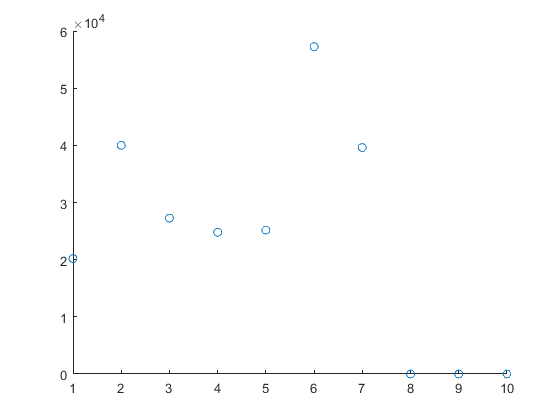

scatter(op,mm11v)

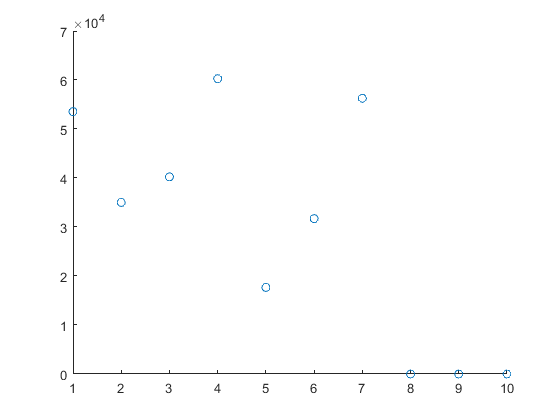

scatter(op,mm22v)

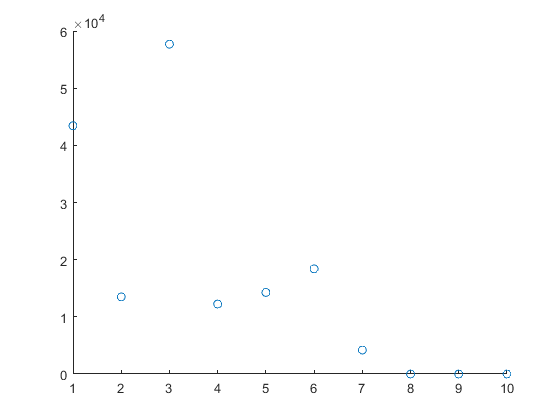

scatter(op,mm33v)

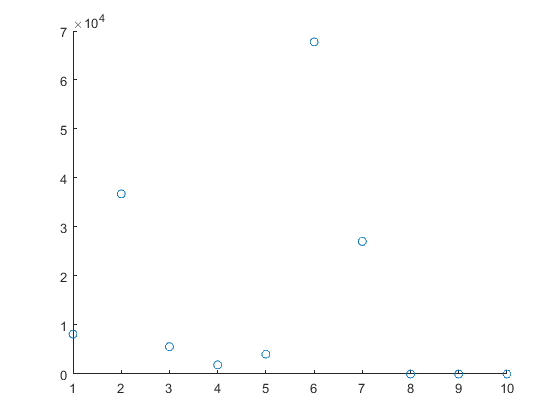

scatter(op,mm12v)

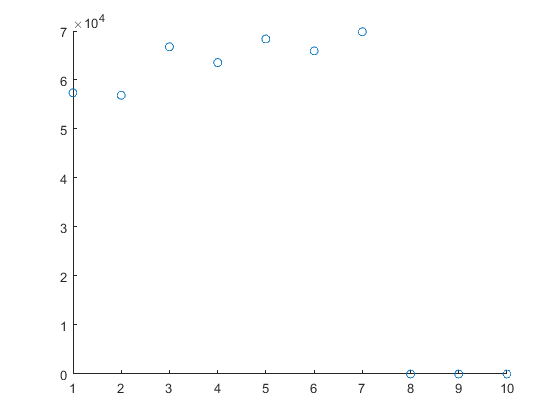

scatter(op,mm31v)

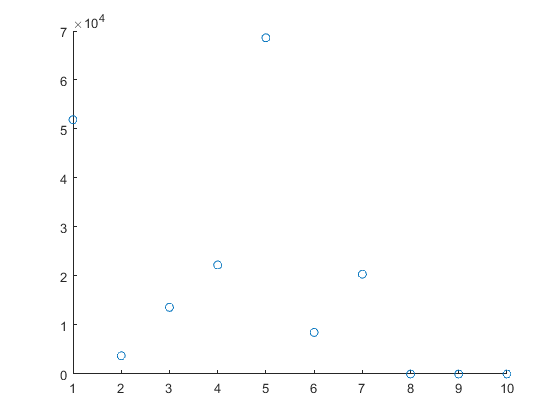

scatter(op,mm32v)